# **EXTRACT**: **t**ractable and **r**obust  **a**utomated **c**ell extraction **t**ool for calcium imaging

It ***extracts*** the activities of cells as time series from both one-photon and two-photon Ca2+ imaging movies

## Introduction to the EXTRACT pipeline

Steps:

- **Input raw movie:** The pipeline takes a raw 1p/2p Ca2+ imaging movie as an  input.

- **Pre-processing:** one performs motion correction and various pre-processing steps.

- **EXTRACT: **The processed movie is used by the EXTRACT algorithm to perform tractable and robust cell extraction.

- **Cell sorting:** One can use either EXTRACT's internal sorter or use an external sorter for this step.

- **Output:** The output consists of temporal traces and spatial maps for future data analysis.

EXTRACT code in this repository provides most of the pipeline (colored as green in the figure). We also provide some links to the external repositories whenever needed (colored as orange in the figure).

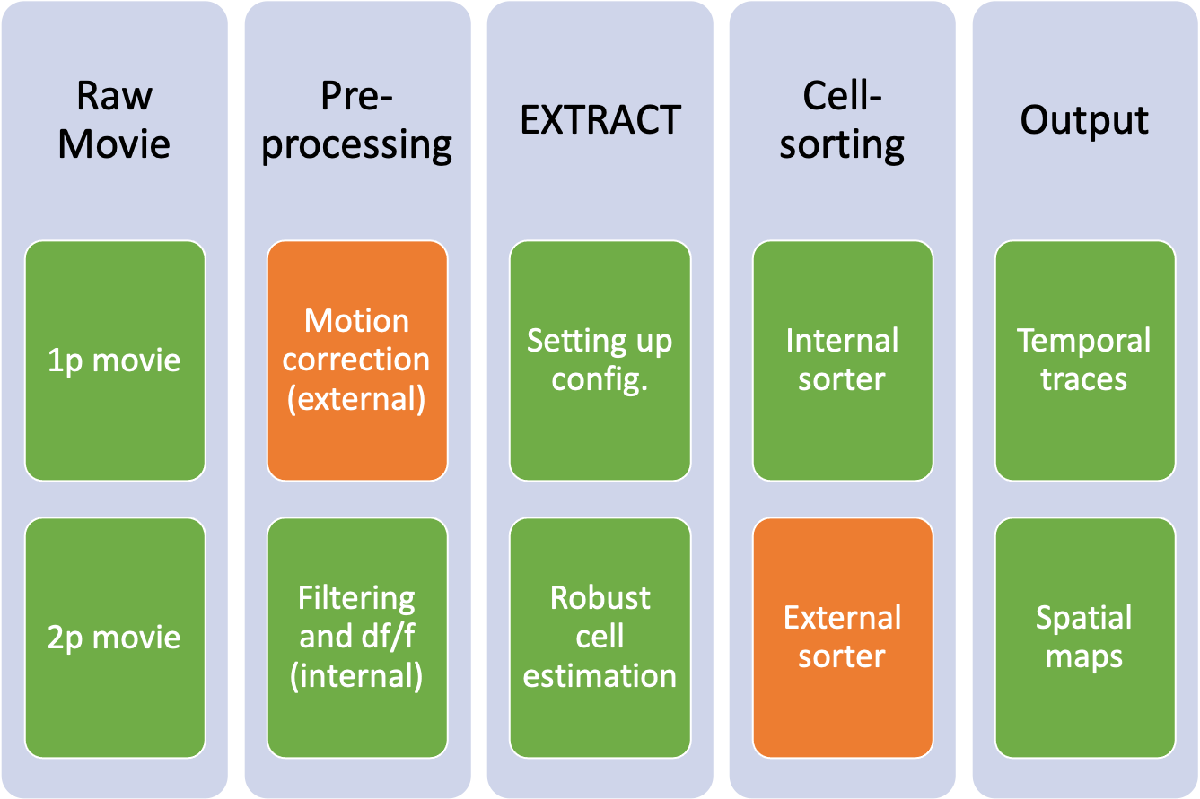

Figure credit: Schnitzer Lab

## **Dependencies**

Before running the utorial, first check that all the dependencies are installed. EXTRACT requires, at least, the following toolboxes. With future releases, there may be need for further toolboxes.

- Bioinformatics Toolbox

- Econometrics Toolbox

- Image Processing Toolbox

- Parallel Computing Toolbox

- Signal Processing Toolbox

- Statistics and Machine Learning Toolbox

- Wavelet Toolbox

## Input

It is a good practice to clear the RAM before loading the input data and performing cell extraction. In this tutorial, the input file (example.mat)

contains a movie M, ground truth spatial cell maps (S_ground), and ground truth time-series traces (T_ground).

clear;
load('example.mat'); 


## Configurations

It is essential to define the configuration to be used for running EXTRACT. To know the full list of advanced configurations and their defaults, see this: [https://github.com/schnitzer-lab/EXTRACT-public#configurations](https://github.com/schnitzer-lab/EXTRACT-public#configurations)

### Default configurations

config = [];
config = get_defaults(config); 


### Essential configuration

It is essential to define the average cell radius, without this EXTRACT will give an error.

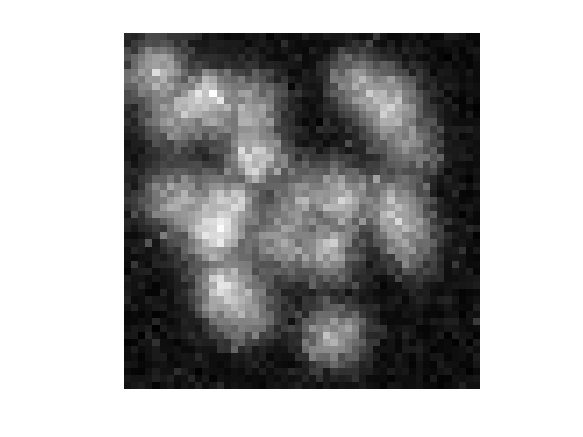


% By considering the maximum projections, pick an estimate cell radius
figure, imshow(max(M,[],3),[]);



config.avg_cell_radius = 7; % Average cell radius is 7.



### Optional configurations

While these are optional, it is strongly advised to handpick the following configurations. 

For this tutorial, the example movie is small enough that EXTRACT will not automatically partition this, but it is a good idea to keep the following in mind. Change the number of partitions for loading movies that won't fit into the RAM. 

config.num_partitions_x=1;
config.num_partitions_y=1; 

Choose the output trace option: 'nonneg' for non-negative Ca2+ traces, 'raw' for raw ones.

config.trace_output_option='raw'; 

If the movie is clean enough (as in this tutorial), there is no need to lowpass filter it. Else use of the spatial smoothing filter options for finding cells.

config.cellfind_filter_type='none';

Keeping verbose=2 gives insight into the EXTRACTion process. It is always advised to keep verbose=2.

config.verbose=2; 

no need for highpass filtering

config.spatial_highpass_cutoff=inf; 

no need for background removal

config.remove_background=0;

### Optional configurations whose defaults exist

This is a small dataset, will be fast on cpu anyways.

config.use_gpu=0; 

10 is a good number of iterations for this dataset.

config.max_iter = 10; 

Adaptive kappa is on for this movie. For an actual movie, keeping it off may be beneficial depending on the noise levels.

config.adaptive_kappa = 1;

Default snr is 1, lower this (never less than 0) to increase cell count at the expense of more spurious cells!

config.cellfind_min_snr=0.5;

## Perform EXTRACTion

output=extractor(M,config);

16-Dec-2021 14:56:02: Signal extraction on partition 1 (of 1):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0203 
	 	 	 	 minimum magnitude: 0.0142 
	 	 	 19 cells found after a total of 21 steps. 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 19 (0 removed) 
	 	 	 End of iter # 2: # cells: 19 (0 removed) 
	 	 	 End of iter # 3: # cells: 19 (0 removed) 
	 	 	 End of iter # 4: # cells: 19 (0 removed) 
	 	 	 End of iter # 5: # cells: 19 (0 removed) 
	 	 	 End of iter # 6: # cells: 19 (0 removed) 
	 	 	 End of iter # 7: # cells: 19 (0 removed) 
	 	 	 End of iter # 8: # cells: 19 (0 removed) 
	 	 	 End of iter # 9: # cells: 19 (0 removed) 
	 	 	 End of iter # 10: # cells: 19 (0 removed) 
	 	 	 Providing raw traces. 
	 	 	 Count: 19 cells.
16-Dec-2021 14:56:32: T

## Matching ground truth to EXTRACTed signals

figure; imshow(output.info.summary_image)

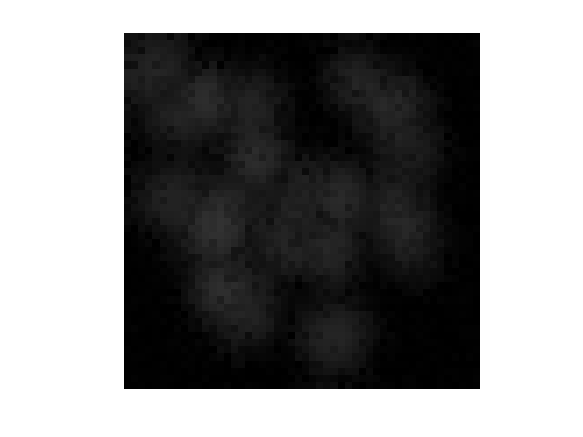

figure; imagesc(output.info.F_per_pixel)

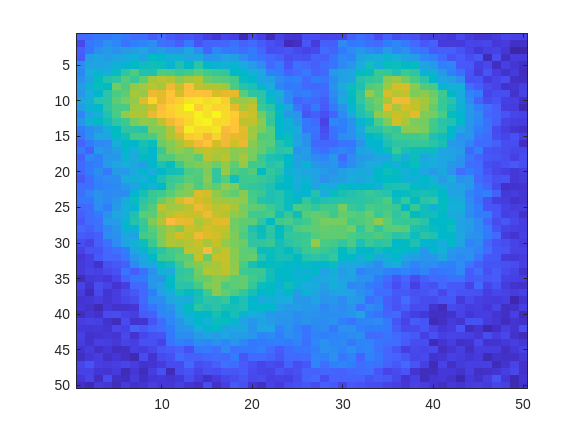

figure; imshow(output.info.max_image)

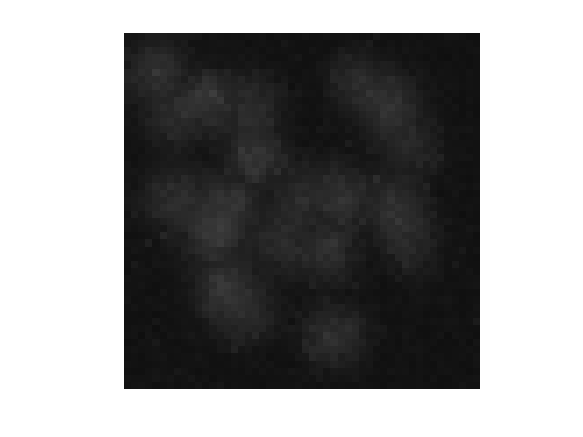

montage(output.spatial_weights)'

Pick a cell number from the 19 EXTRACTed cells and display its spatial weights. Note that as per the ground truth, there are 20 cells. 

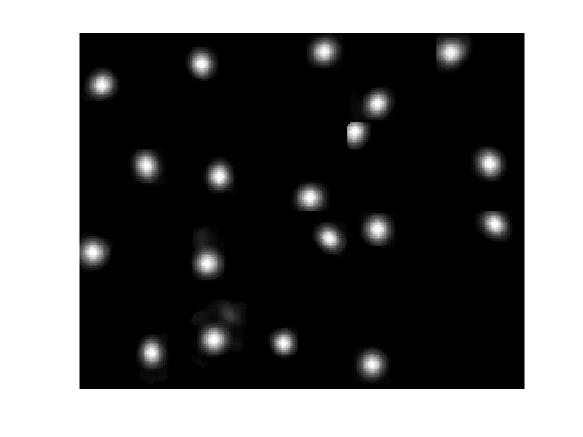

ans =   Image with properties:

           CData: [864×1080 single]
    CDataMapping: 'scaled'

  Show all properties


pick=19; 

figure;
imagesc(output.spatial_weights(:,:,pick)')

figure;
imshow(output.spatial_weights(:,:,pick)')

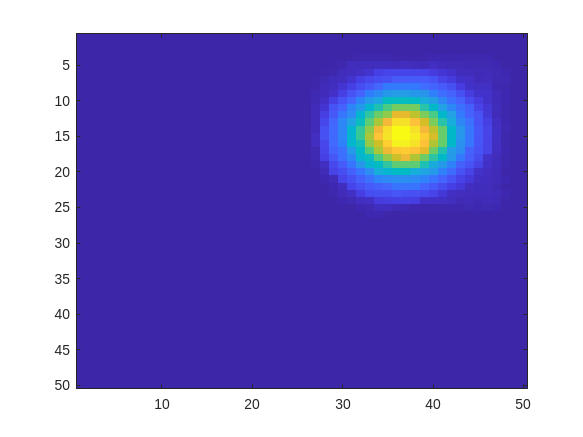

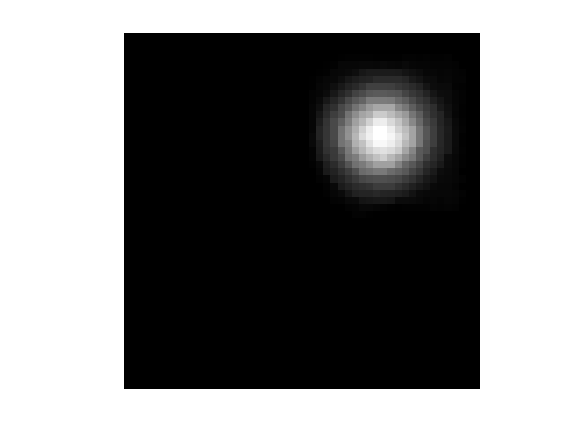


[h,w,k]=size(full(output.spatial_weights));
S_ex=reshape(full(output.spatial_weights),h*w,k);

idx_match = match_sets(S_ex, S_ground); %this is a very useful helper function, use this as you need!

T_ex = output.temporal_weights';

## Perform multivariate linear regression for comparison

M_res=reshape(M,2500,2000);
X=mean(M_res,2);
M_res=(M_res-X)./X; %perform dfof
S=S_ex;
T_est=(S'*S)^(-1)*S'*M_res;
% Since this movie does not contain unfound cells or neuropils, this will
% be close to ground truth and EXTRACT outputs!


plot(T_ex(idx_match(1,pick),:));
hold on
plot(T_ground(idx_match(2,pick),:))
hold on
plot(T_est(idx_match(1,pick),:))